clc;
clear;
runtime=80

runtime = 80

for count=1:runtime
Road_length  =150;
car_number   = 80;
acceleration = 2+0.1*count
deceleration =-6.5;
a_d(count)=abs(acceleration/deceleration)
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:40
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
S(count)=std(m);
averagespeed(count) = mean(m);
acc(count)=acceleration;
%percentage
end

acceleration = 2.1000

a_d = 0.3231

acceleration = 2.2000

a_d =     0.3231    0.3385


acceleration = 2.3000

a_d =     0.3231    0.3385    0.3538


acceleration = 2.4000

a_d =     0.3231    0.3385    0.3538    0.3692


acceleration = 2.5000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846


acceleration = 2.6000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000


acceleration = 2.7000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154


acceleration = 2.8000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308


acceleration = 2.9000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462


acceleration = 3

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615


acceleration = 3.1000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769


acceleration = 3.2000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923


acceleration = 3.3000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077


acceleration = 3.4000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231


acceleration = 3.5000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385


acceleration = 3.6000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538


acceleration = 3.7000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692


acceleration = 3.8000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846


acceleration = 3.9000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000


acceleration = 4

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154


acceleration = 4.1000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308


acceleration = 4.2000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462


acceleration = 4.3000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615


acceleration = 4.4000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769


acceleration = 4.5000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923


acceleration = 4.6000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077


acceleration = 4.7000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231


acceleration = 4.8000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385


acceleration = 4.9000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538


acceleration = 5

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 5.1000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846


acceleration = 5.2000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000


acceleration = 5.3000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154


acceleration = 5.4000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308


acceleration = 5.5000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462


acceleration = 5.6000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615


acceleration = 5.7000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769


acceleration = 5.8000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923


acceleration = 5.9000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077


acceleration = 6

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231


acceleration = 6.1000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385


acceleration = 6.2000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538


acceleration = 6.3000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692


acceleration = 6.4000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846


acceleration = 6.5000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000


acceleration = 6.6000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154


acceleration = 6.7000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154    1.0308


acceleration = 6.8000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154    1.0308    1.0462


acceleration = 6.9000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154    1.0308    1.0462    1.0615


acceleration = 7

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154    1.0308    1.0462    1.0615    1.0769


acceleration = 7.1000

a_d =     0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692    0.7846    0.8000    0.8154    0.8308    0.8462    0.8615    0.8769    0.8923    0.9077    0.9231    0.9385    0.9538    0.9692    0.9846    1.0000    1.0154    1.0308    1.0462    1.0615    1.0769


acceleration = 7.2000

a_d = 1×52
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.3000

a_d = 1×53
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.4000

a_d = 1×54
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.5000

a_d = 1×55
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.6000

a_d = 1×56
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.7000

a_d = 1×57
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.8000

a_d = 1×58
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 7.9000

a_d = 1×59
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8

a_d = 1×60
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.1000

a_d = 1×61
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.2000

a_d = 1×62
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.3000

a_d = 1×63
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.4000

a_d = 1×64
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.5000

a_d = 1×65
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.6000

a_d = 1×66
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.7000

a_d = 1×67
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.8000

a_d = 1×68
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 8.9000

a_d = 1×69
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9

a_d = 1×70
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.1000

a_d = 1×71
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.2000

a_d = 1×72
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.3000

a_d = 1×73
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.4000

a_d = 1×74
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.5000

a_d = 1×75
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.6000

a_d = 1×76
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.7000

a_d = 1×77
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.8000

a_d = 1×78
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 9.9000

a_d = 1×79
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


acceleration = 10

a_d = 1×80
    0.3231    0.3385    0.3538    0.3692    0.3846    0.4000    0.4154    0.4308    0.4462    0.4615    0.4769    0.4923    0.5077    0.5231    0.5385    0.5538    0.5692    0.5846    0.6000    0.6154    0.6308    0.6462    0.6615    0.6769    0.6923    0.7077    0.7231    0.7385    0.7538    0.7692


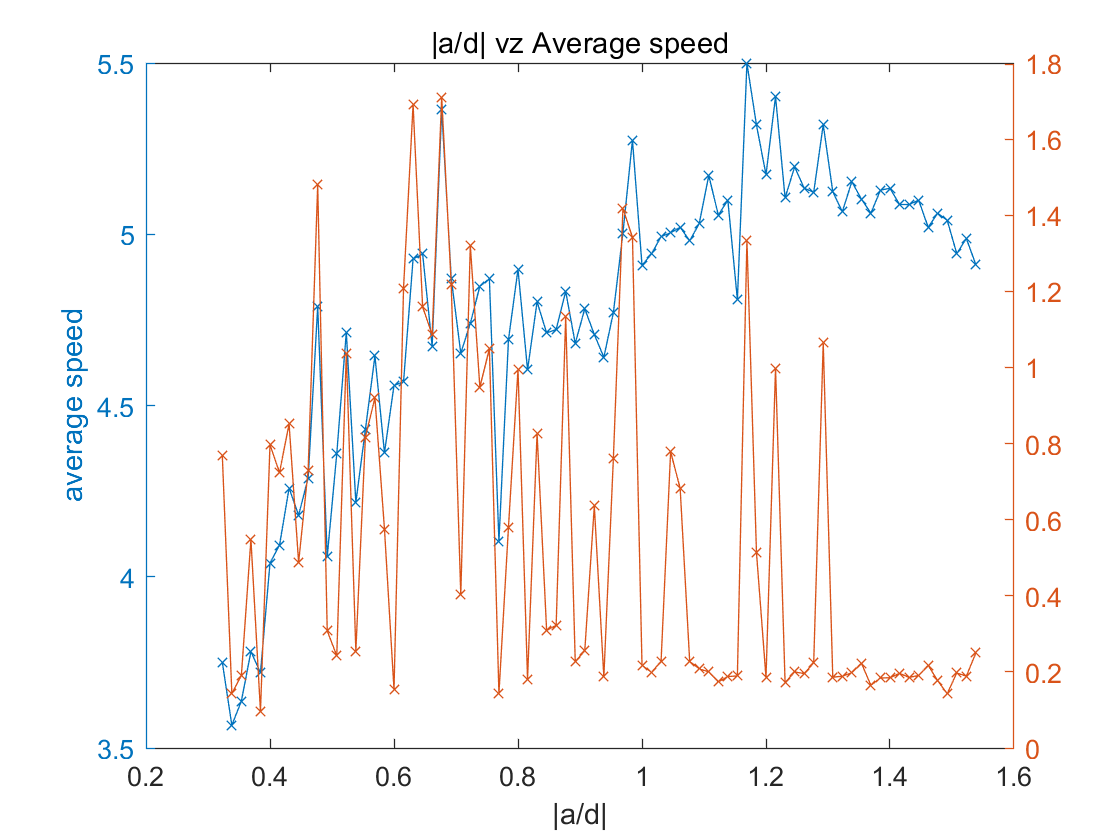

错误使用 smoothdata (第 111 行)
输入参数的数目不足。

yyaxis left
plot(a_d,averagespeed,"-x","MarkerSize",5)
title("|a/d| vz Average speed") 
xlabel('|a/d|')
ylabel('average speed')

yyaxis right
plot(a_d,S,"-x","MarkerSize",5)

ylabel('standard deviation')


% 对输入数据进行平滑处理
smoothedData = smoothdata(S,'movmean','SmoothingFactor',0.25);

% 显示结果
clf
plot(S,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend

